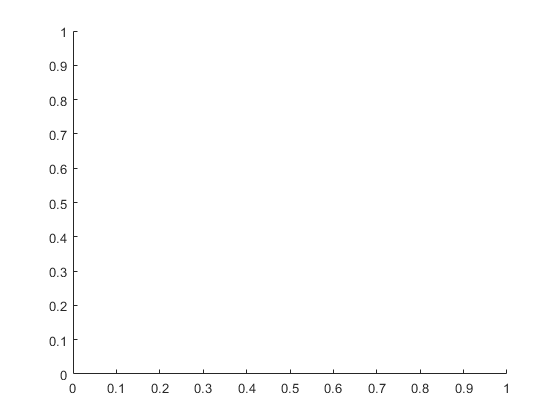

   36.7708



    0.7542



% analyse whole file
% this is used with each set of test to convert AE signal of waveguide
% senosrs into wavelet image
parentDir = 'G:\PHD Data & Files\CNN with AE\Data';
dataDir = 'data';
listing = dir (fullfile(parentDir, '*.mat'));
for j= 1: length(listing)
    j=1
    file = listing(j).name;
    mkdir(fullfile(parentDir,dataDir, file)); % udpate name to folder accroding to test type.
    
    % load mat file into workspace to proccess signals
    path =  listing(j).folder;
    %[file path]= uigetfile('*.mat');
    load([path '\' file])
    imagRoot = ['G:\PHD Data & Files\CNN with AE\Data\data\' file ];
    % calculate and update data structure with RMS for signals
    
    %---------------------------------------------------------------------------------------------------------------------------
    % Calculating gas turbine speed from optical sensor signal.
    
    for i= 1:length(Data)
        
        % calculte turbine speed
        yn=Data(i).speedSignalFpt;
        data_n =yn; thresh = 0;
        above = find(data_n>thresh);clear data_ht thresh;
        above_d = diff(above);
        notone = find(above_d~=1);clear above_d;
        above_event2 = above(notone+1);clear notone;
        above_event = [above(1); above_event2];clear above above_event2;
        n_count = length(above_event);
        Nr=(n_count/35)/0.03;
        Data(i).speedFptRPM =Nr*60;
        
        % calcule rms
        y= Data(i).waveGuide;
        y= y-mean(y);
        Data(i).waveGuideRMS = rms(y);
        Data(i).waveGuideSTD = std(y);
    end
    
    
    %------------------------------------------------------------------------------------------------------
    % this code create pictures for whole signal with demodulated signal
    downSampleRate = 5;
    for i= 1:length(Data)
        
        Fs = Data(i).SmaplingRate; % get data sampling rate
        sig = Data(i).waveGuide; % get data signal
        sig = downsample(sig,downSampleRate); % frequency over 1.25 Mhz not very affective so they have been removed
        sig = lowpass(sig,(Fs/10)-1,Fs/5,'ImpulseResponse','iir','Steepness',0.95); % lowpass filter to remove any alaising
        t = Data(i).time; % get signal time
        t= downsample(t,downSampleRate); % downsample time
        [up,lo] = envelope(sig); % get signal envelop to perform demodulted frequency later
        uplowpass= lowpass(up,(Fs/200)-1,Fs/5,'ImpulseResponse','iir','Steepness',0.95); % lowpass filter to remove any
        uplowpass = downsample(uplowpass,10); % no need for the frequecy that removed by lowpass filter
        uplowpass = uplowpass- mean(uplowpass); % remove the mean to get better frequencyy resuts
        Data(i).waveGuideKurt= kurtosis(uplowpass);
        sigLength = length(uplowpass);
        if i==1 || sigPre ~= sigLength
            sigPre = length(sig);
            fb = cwtfilterbank('SignalLength',sigLength,'VoicesPerOctave',26);
        end
        cfs = abs(fb.wt(uplowpass));
        cfs = imresize(cfs,[256 256]);
        Numcolor=256;
        newmap=gray(256);
        %newmap(:,3)=(Data(i).speedFptRPM)/20000;     % Normalize speed to maximum turbine speed 20000 rpm
        newmap(:,3)=(Data(i).waveGuideKurt/380);      % Normalize to maximum kurtosis
        newmap(:,2)=Data(i).waveGuideRMS/2.5;            % Use rms as blue colour. rms represent energy and most of rms is bleow 1
        colormap(newmap);
        caxis([0,256]);
        InImgNormalized=cfs./rms(sig);
        colormap(newmap);
        im = ind2rgb(im2uint8(InImgNormalized),colormap(newmap));
        imFileName = strcat(file,'_',num2str(i),'.jpg');
        imwrite(imresize(im,[224 224]),fullfile(imagRoot,imFileName));
    end
    disp(max(extractfield(Data, 'waveGuideKurt')))
    disp(max(extractfield(Data, 'waveGuideRMS')))
    save([path '\' file],'Data','-v7.3')
end

axis off    %Remove axes
    colorbar off    %Remove colorbar
    set(gca,'LooseInset',get(gca,'TightInset'));    %Remove background
    set(gca,'units','normalized','position',[0 0 1 1]);     %Remove additional background
    fig2 = getframe(fh);   %Get 'image' from figure
    image = fig2.cdata;     %Imgage data
    image = imresize(image, [224 224]); %Resize image
    imwrite(image, 'mypic.jpg');
    imFileName = strcat('D2','_',num2str(i),'.jpg');
    imwrite(image,fullfile(imagRoot,imFileName));
    close all
 